# Explore the FRF characteristics of a finite width **Rectangular Pulse**

Consider the time domain signal shown below - a **Rectangular Pulse** of width $T$ seconds:

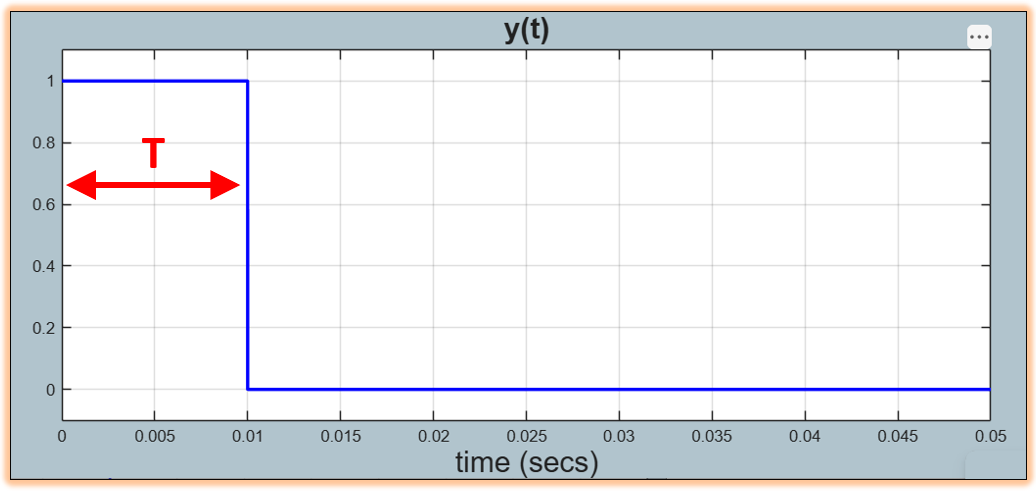

Let's derive the following:

- The Frequency response Function (FRF) of the pulse $Y\left(\omega \right)$

- The DC gain of the FRF, i.e.:  $Y\left(\omega =0\right)$

- What frequency do we get a 3dB drop from DC ?

`Bradley Horton: bhorton@mathworks.com`

## Clear Workspace AND the Symbolic engine

clear all  % ALL is needed to clear any existing ASSUMPTIONS

assumptions

 
ans =
 
Empty sym: 1-by-0
 


## Define symbolic variables

syms t T omega s

assume(t, "real")
assume(T, "real")
assume(omega, "real")
assumeAlso(T > 0)

assumptions

$$ans = \left(\begin{array}{cccc} T\in \mathbb{R} & \omega \in \mathbb{R} & t\in \mathbb{R} & 0<T \end{array}\right)$$

## Exploration - Part_1

Define a rectangular pulse of width T

y = heaviside(t) - heaviside(t-T)

$$y = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-T\right)$$

Create $Y\left(s\right)$ 

Ys = laplace(y)

$$Ys = \frac{1}{s}-\frac{{\mathrm{e}}^{-T\,s}}{s}$$

## Exploration - Part_2

Going Manual mode now.  So we have

- 
$$Y\left(s\right)\;\;=\;\;\frac{1\;\;-\;e^{-\mathrm{Ts}} }{s}\;\;\;=\;\;\;\frac{e^{\frac{-\mathrm{Ts}}{2}} \ldotp \left(e^{\frac{\mathrm{Ts}}{2}} \;\;-\;\;e^{\frac{-\mathrm{Ts}}{2}} \right)}{s}$$


Now to get the FRF, substitute $s=j\ldotp \omega$

- 
$$Y\left(\omega \right)\;\;=\;\;\;\;\;\frac{e^{\frac{-\mathrm{jT}\omega }{2}} \ldotp \left(e^{\frac{\mathrm{jT}\omega }{2}} \;\;-\;\;e^{\frac{-\mathrm{jT}\omega }{2}} \right)}{j\ldotp \omega }$$


And recognizing that:

- 
$$e^{i\theta } \;-e^{-i\theta } \;=\;2\ldotp i\ldotp \sin \left(\theta \right)$$


So our FRF expression becomes:

- 
$$Y\left(\omega \right)\;\;=\;\;\;\;\;\frac{e^{\frac{-\mathrm{jT}\omega }{2}} \ldotp \left\lbrack 2\ldotp j\ldotp \sin \left(\frac{T\ldotp \omega }{2}\right)\right\rbrack }{j\ldotp \omega }$$


So we finally have:

- 
$$Y\left(\omega \right)\;\;=\;\;\;\;\;\frac{e^{\frac{-\mathrm{jT}\omega }{2}} \ldotp 2\ldotp \sin \left(\frac{T\ldotp \omega }{2}\right)}{\omega }$$


### So the FRF of the pulse is:

- 
$$\left|Y\left(\omega \right)\right|\;\;=\;\left|\frac{2\ldotp \sin \left(\frac{T\ldotp \omega }{2}\right)}{\omega }\right|$$


### What's it's DC gain ?

Also, recall from the [Taylor series expansion](https://en.wikipedia.org/wiki/Taylor_series) for $\sin \left(\theta \right)$

- 
$$\sin \left(\theta \right)\;\;=\;\;\theta \;-\;\;\frac{\theta^3 }{3!}\;\;+\;\frac{\theta^5 }{5!}\;-\;\;\frac{\theta^7 }{7!}\;\;\ldotp \ldotp \ldotp$$


So ? - So:

- 
$$\lim_{\omega \to 0} \left|Y\left(\omega \right)\right|\;\;=\;2\ldotp \left(\frac{T}{2}\right)=T\;$$


### What frequency do we get a 3dB drop from DC ?

And lastly let's define the bandwidth for a 3dB signal reduction from $\omega =0$

Recall:

- $-3\;\mathrm{dB}\;=20\ldotp {\mathrm{Log}}_{10} \left(\left|\frac{Y\left(\omega \right)}{Y\left(0\right)}\right|\right)$    So      $\frac{1}{\sqrt{2}}\;\;\;=\;\;\;0\ldotp 7071\;\;=\left|\frac{Y\left(\omega \right)}{Y\left(0\right)}\right|\;=\frac{\left|Y\left(\omega \right)\right|}{T}$

So:

- 
$$\frac{T}{\sqrt{2}}\;=\;\;\frac{2\ldotp \sin \left(\frac{T\ldotp \omega }{2}\right)}{\omega }\;\;=\;\;\;\frac{2\ldotp \sin \left(\frac{T\ldotp \omega }{2}\right)}{\frac{T\ldotp \omega }{2}}\ldotp \left(\frac{\frac{T}{2}}{1}\right)$$


So:

- 
$$\frac{1}{\sqrt{2}}\;=\;\;\;\frac{2\ldotp \sin \left(\frac{T\ldotp \omega }{2}\right)}{\frac{T\ldotp \omega }{2}}\ldotp \left(\frac{\frac{1}{2}}{1}\right)\;\;\;\Longrightarrow \;\;\;\frac{1}{\sqrt{2}}\;=\;\frac{\sin \left(\frac{T\ldotp \omega }{2}\right)}{\frac{T\ldotp \omega }{2}}$$


Which has the form:

- $\frac{1}{\sqrt{2}}\;=\;\frac{\sin \left(x\right)}{x}$     where   $x=\frac{T\ldotp \omega }{2}$

x = fzero( @(x) sqrt(1/2) - sin(x)./x, 1)

x = 1.3916

**So our 3dB bandwidth frequency is:**

- 
$$\omega_{3\mathrm{dB}} \;\;\;=\;\;\frac{2\;\ldotp \left(1\ldotp 3916\right)}{T}\;\;=\;\;\frac{2\ldotp 7832}{T}\;\;\;\;\left(\frac{\mathrm{rad}}{\left.\sec \right)}\right)$$
   

- 
$$f_{3\mathrm{dB}} \;\;\;=\;\frac{\omega_{3\mathrm{dB}} }{2\ldotp \pi }\;\;=\;\;\frac{0\ldotp 4430}{T}\;\;\;\;\left(\mathrm{Hz}\right)$$


## So let's implement

mag_Yw = abs(2*sin(T*omega/2) / omega);

Create a function handle for plotting and evaluating

FH_mag_Yw = matlabFunction(mag_Yw, Vars=[omega, T])

FH_mag_Yw = function_handle with value:
    @(omega,T)(abs(sin((T.*omega)./2.0)).*2.0)./abs(omega)


## Visualize

Define the Pulse width in seconds

T_val     = 0.002;  % (secs)

Plot the time domain signal

y_t = heaviside(t) - heaviside(t-T_val)

$$y\_t = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-\frac{1}{500}\right)$$

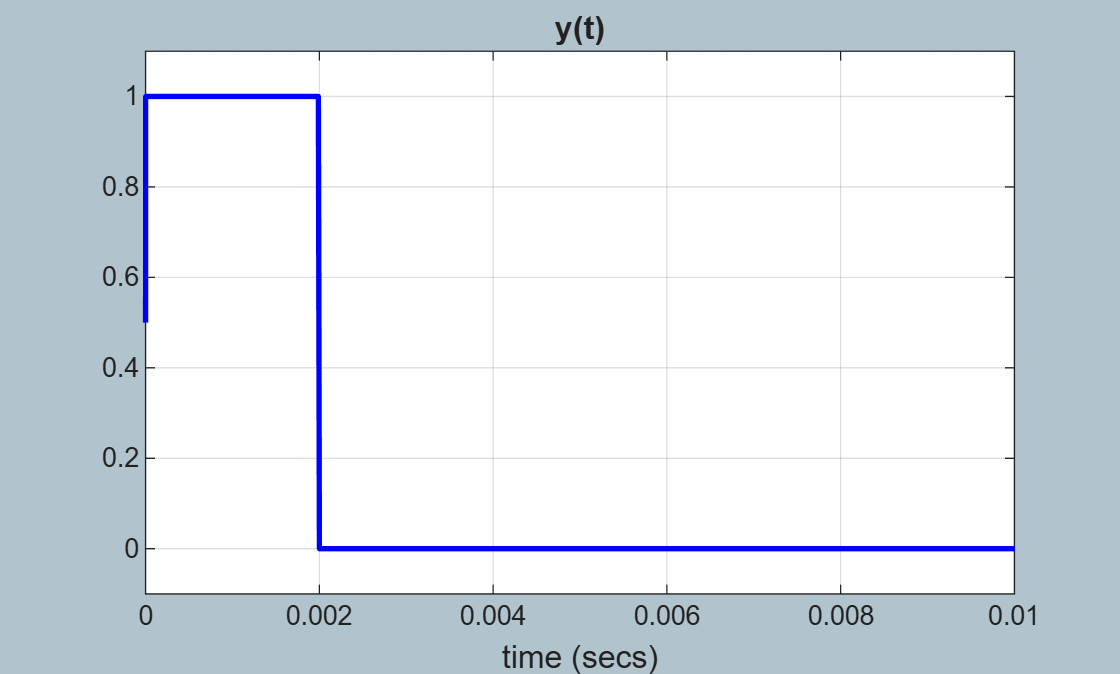


figure;
    fplot(y_t, [0, 5*T_val], "-b", LineWidth=2);
        xlabel("time (secs)", "FontSize",12);
        grid("on")
        ylim([-0.1, 1.1]);
        title("y(t)", "FontSize",12)

Plot the Frequency domain of the signal

fhz_list  = 0.0001:0.01:1e3;
w_list    = 2*pi*fhz_list;
my_Y      = FH_mag_Yw(w_list, T_val);
%my_Y(1)   = A; % the limit as w-->0

figure;
    plot(fhz_list, 20*log10(my_Y), "-r", LineWidth=2);
        xlabel("(Hz)"); ylabel("(dB)"); grid("on")  
        title("|Y(\omega)|")

Where is the 3dB drop ?

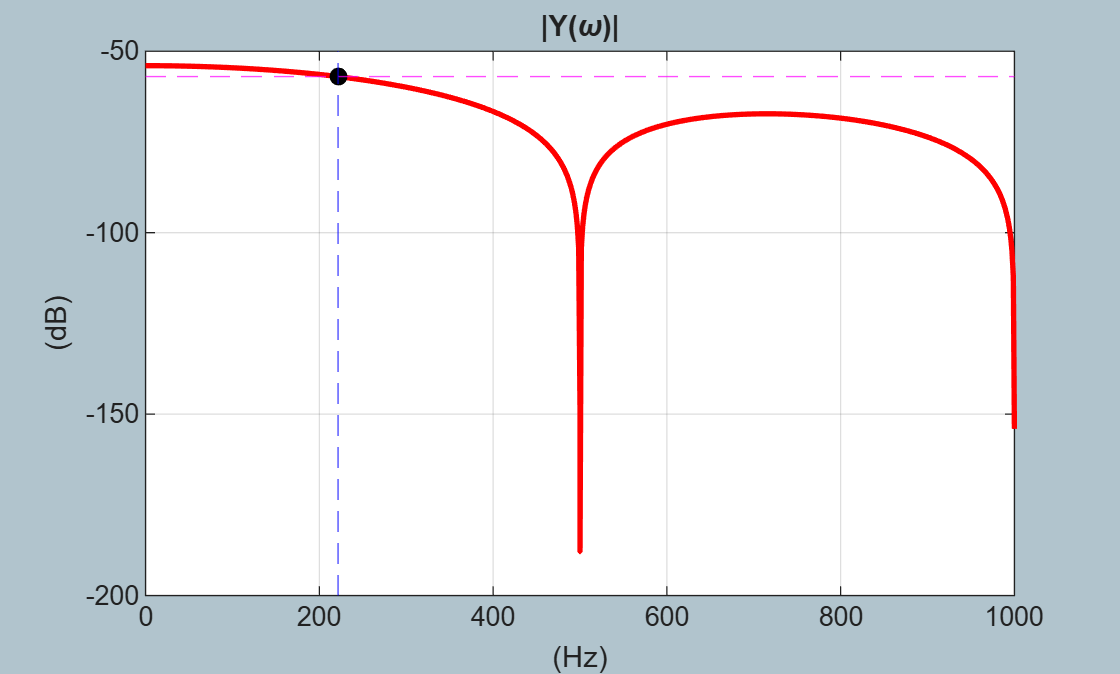


hold on
    yline(20*log10(T_val)-3, "--m")
    xline((0.443/T_val), "--b")
    plot( (0.443/T_val), 20*log10(T_val)-3, ".k", MarkerSize=20)

fprintf("\n ... 3dB drop at f=%.2f", (2.7832/T_val)/(2*pi) ) 


 ... 3dB drop at f=221.48

## Clean up:

Remove the assumptions from teh Symbolic Toolbox engine

%assume([t A omega],"clear")
assume(t,"clear")
assume(T,"clear")
assume(omega,"clear")
assumptions()

 
ans =
 
Empty sym: 1-by-0
 
